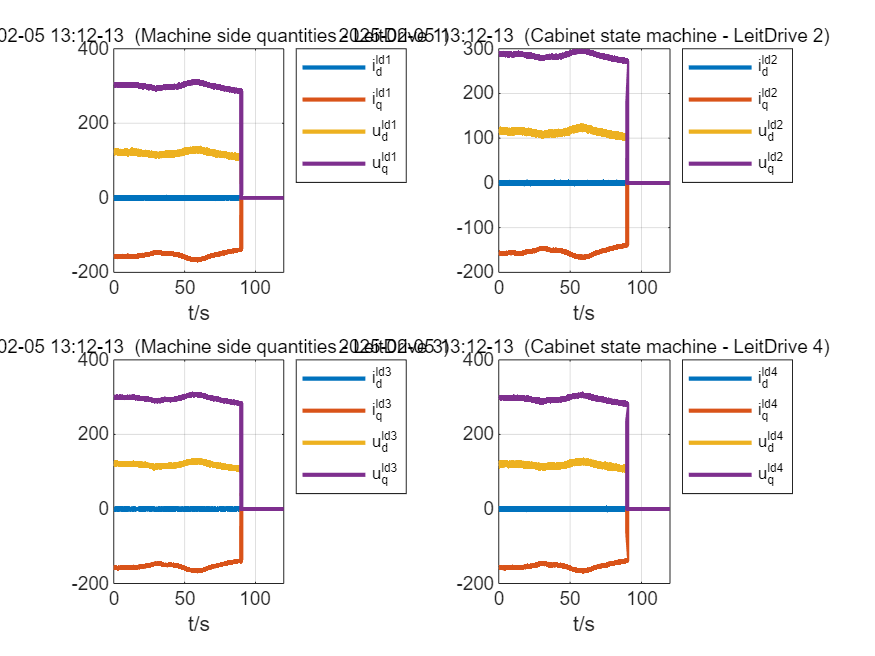

tratto1=2;
tratto2=2;
tratto3=2;
colore1 = [0.25 0.25 0.25];
colore2 = [0.5 0.5 0.5];
colore3 = [0.75 0.75 0.75];
colore4 = [0 0 0];

T = 120/M;
t = [0:T:(M-1)*T];
t1 = t(1);
t2 = t(end);

fig1 = figure;
subplot 221
plot(t,MondId_ld1,t,MondIq_ld1,t,MondUd_ld1,t,MondUq_ld1,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(Machine side quantities - LeitDrive 1)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('i_d^{ld1}','i_q^{ld1}','u_d^{ld1}','u_q^{ld1}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('')
grid on
subplot 222
plot(t,MondId_ld2,t,MondIq_ld2,t,MondUd_ld2,t,MondUq_ld2,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(Cabinet state machine - LeitDrive 2)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('i_d^{ld2}','i_q^{ld2}','u_d^{ld2}','u_q^{ld2}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('')
grid on
subplot 223
plot(t,MondId_ld3,t,MondIq_ld3,t,MondUd_ld3,t,MondUq_ld3,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(Machine side quantities - LeitDrive 3)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('i_d^{ld3}','i_q^{ld3}','u_d^{ld3}','u_q^{ld3}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('')
grid on
subplot 224
plot(t,MondId_ld4,t,MondIq_ld4,t,MondUd_ld4,t,MondUq_ld4,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(Cabinet state machine - LeitDrive 4)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('i_d^{ld4}','i_q^{ld4}','u_d^{ld4}','u_q^{ld4}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('')
grid on
set(fig1,'PaperSize',fliplr(get(fig1,'PaperSize'))) 
print(fig1,'-fillpage','-dpdf','figure_1') 

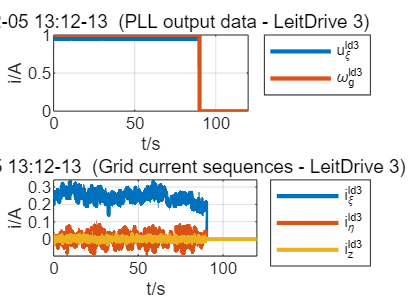


fig2 = figure;
subplot 211
plot(t,PllUxiGrid_ld3,t,PllOmega_ld3,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(PLL output data - LeitDrive 3)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('u_{\xi}^{ld3}','\omega_{g}^{ld3}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('i/A')
grid on
subplot 212
plot(t,LinecIGridPosXi_ld3,...
    t,LinecIGridPosEta_ld3,t,...
    LinecIGridZero_ld3,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(Grid current sequences - LeitDrive 3)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('i_{\xi}^{ld3}','i_{\eta}^{ld3}','i_{z}^{ld3}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('i/A')
grid on
set(fig2,'PaperSize',fliplr(get(fig2,'PaperSize'))) 
print(fig2,'-fillpage','-dpdf','figure_2') 

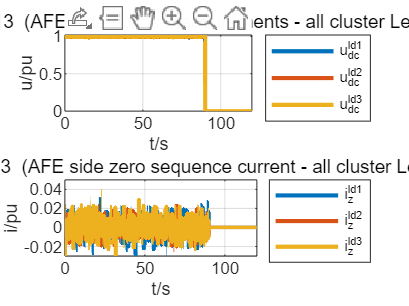


fig3 = figure;
subplot 211
plot(t,AfeAdcdUdc_ld1,t,AfeAdcdUdc_ld2,t,AfeAdcdUdc_ld3,t,AfeAdcdUdc_ld4,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(AFE side dclink measurements - all cluster LeitDrives)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('u_{dc}^{ld1}','u_{dc}^{ld2}','u_{dc}^{ld3}','u_{dc}^{ld4}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('u/pu')
grid on
subplot 212
plot(t,LinecIGridZero_ld1,t,LinecIGridZero_ld2,t,LinecIGridZero_ld3,t,LinecIGridZero_ld4,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(AFE side zero sequence current - all cluster LeitDrives)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('i_{z}^{ld1}','i_{z}^{ld2}','i_{z}^{ld3}','i_{z}^{ld4}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('i/pu')
grid on
set(fig3,'PaperSize',fliplr(get(fig3,'PaperSize'))) 
print(fig3,'-fillpage','-dpdf','figure_3') 

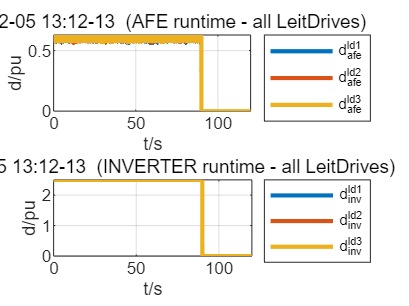


fig4 = figure;
subplot 211
plot(t,AfeRuntimeFast_ld1,t,AfeRuntimeFast_ld2,t,AfeRuntimeFast_ld3,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(AFE runtime - all LeitDrives)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('d_{afe}^{ld1}','d_{afe}^{ld2}','d_{afe}^{ld3}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('d/pu')
grid on
subplot 212
plot(t,InvRuntimeFast_ld1,t,InvRuntimeFast_ld2,t,InvRuntimeFast_ld3,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(INVERTER runtime - all LeitDrives)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('d_{inv}^{ld1}','d_{inv}^{ld2}','d_{inv}^{ld3}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('d/pu')
grid on
set(fig4,'PaperSize',fliplr(get(fig4,'PaperSize'))) 
print(fig4,'-fillpage','-dpdf','figure_4') 

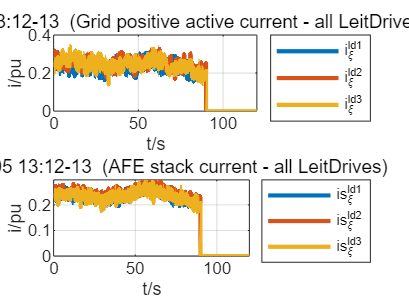


fig5 = figure;
subplot 211
plot(t,LinecIGridPosXi_ld1,t,LinecIGridPosXi_ld2,t,LinecIGridPosXi_ld3,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(Grid positive active current - all LeitDrives)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('i_{\xi}^{ld1}','i_{\xi}^{ld2}','i_{\xi}^{ld3}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('i/pu')
grid on
subplot 212
plot(t,LinecIStackXi_ld1,t,LinecIStackXi_ld2,t,LinecIStackXi_ld3,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(AFE stack current - all LeitDrives)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('is_{\xi}^{ld1}','is_{\xi}^{ld2}','is_{\xi}^{ld3}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('i/pu')
grid on
set(fig5,'PaperSize',fliplr(get(fig5,'PaperSize'))) 
print(fig5,'-fillpage','-dpdf','figure_5') 

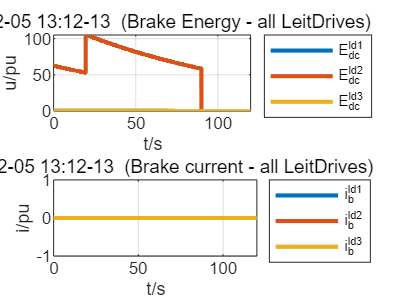


fig6 = figure;
subplot 211
plot(t,MondBrakeEnergy_ld1,t,MondBrakeEnergy_ld2,t,MondBrakeEnergy_ld3,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(Brake Energy - all LeitDrives)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('E_{dc}^{ld1}','E_{dc}^{ld2}','E_{dc}^{ld3}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('u/pu')
grid on
subplot 212
plot(t,MondIBrakeFiltered_ld1,t,MondIBrakeFiltered_ld2,t,MondIBrakeFiltered_ld3,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(Brake current - all LeitDrives)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('i_{b}^{ld1}','i_{b}^{ld2}','i_{b}^{ld3}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('i/pu')
grid on
set(fig6,'PaperSize',fliplr(get(fig6,'PaperSize'))) 
print(fig6,'-fillpage','-dpdf','figure_6') 

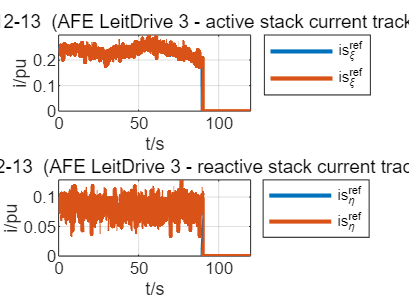


fig7 = figure;
subplot 211
plot(t,LinecIStackXiRef_ld3,t,LinecIStackXi_ld3,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(AFE LeitDrive 3 - active stack current tracking)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('is_{\xi}^{ref}','is_{\xi}^{ref}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('i/pu')
grid on
subplot 212
plot(t,LinecIStackEtaRef_ld3,t,LinecIStackEta_ld3,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(AFE LeitDrive 3 - reactive stack current tracking)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('is_{\eta}^{ref}','is_{\eta}^{ref}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('i/pu')
grid on
set(fig7,'PaperSize',fliplr(get(fig7,'PaperSize'))) 
print(fig7,'-fillpage','-dpdf','figure_7') 

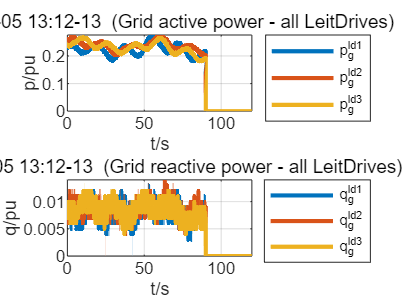


fig8 = figure;
subplot 211
plot(t,LinecPwrActPu_ld1,t,LinecPwrActPu_ld2,t,LinecPwrActPu_ld3,t,LinecPwrActPu_ld4,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(Grid active power - all LeitDrives)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('p_{g}^{ld1}','p_{g}^{ld2}','p_{g}^{ld3}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('p/pu')
grid on
subplot 212
plot(t,LinecPwrReactPu_ld1,t,LinecPwrReactPu_ld2,t,LinecPwrReactPu_ld3,t,LinecPwrReactPu_ld4,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(Grid reactive power - all LeitDrives)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('q_{g}^{ld1}','q_{g}^{ld2}','q_{g}^{ld3}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('q/pu')
grid on
set(fig8,'PaperSize',fliplr(get(fig8,'PaperSize'))) 
print(fig8,'-fillpage','-dpdf','figure_8') 

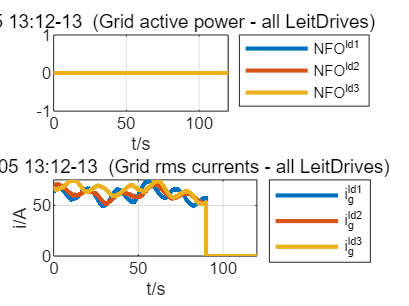


fig9 = figure;
subplot 211
plot(t,MotorcNfo_ld1,t,MotorcNfo_ld2,t,MotorcNfo_ld3,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(Grid active power - all LeitDrives)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('NFO^{ld1}','NFO^{ld2}','NFO^{ld3}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('')
grid on
subplot 212
plot(t,MondIUGridRms_ld1,t,MondIUGridRms_ld2,t,MondIUGridRms_ld3,t,MondIUGridRms_ld4,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(Grid rms currents - all LeitDrives)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('i_{g}^{ld1}','i_{g}^{ld2}','i_{g}^{ld3}','i_{g}^{ld4}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('i/A')
grid on
set(fig9,'PaperSize',fliplr(get(fig9,'PaperSize'))) 
print(fig9,'-fillpage','-dpdf','figure_9') 

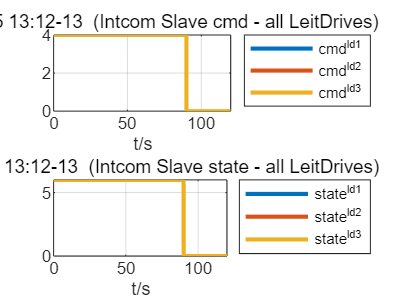


fig10 = figure;
subplot 211
plot(t,IntcomdSlaveCmd_ld1,t,IntcomdSlaveCmd_ld2,t,IntcomdSlaveCmd_ld3,t,IntcomdSlaveCmd_ld4,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(Intcom Slave cmd - all LeitDrives)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('cmd^{ld1}','cmd^{ld2}','cmd^{ld3}','cmd^{ld4}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('')
grid on
subplot 212
plot(t,IntcomdSlaveState_ld1,t,IntcomdSlaveState_ld2,t,IntcomdSlaveState_ld3,t,IntcomdSlaveState_ld4,'LineWidth',tratto1);
tit = title(strcat(spec_file,tab,tab,'(Intcom Slave state - all LeitDrives)'));
tit.FontWeight = 'normal';
tit.FontSize = 9;
set(gca,'xlim',[t1 t2]);
legend('state^{ld1}','state^{ld2}','state^{ld3}','state^{ld4}','Location','NorthEastOutside');
xlabel('t/s');
ylabel('')
grid on
set(fig10,'PaperSize',fliplr(get(fig10,'PaperSize'))) 
print(fig10,'-fillpage','-dpdf','figure_10') 